# **OOI Biology Workshop: Data Report **

# Data Evalutor: Kristen Fogaren

Summary: This code evalutes the data from the CTD on the Oregon Shelf Benthic Package using discrete samples from 5 cruises from December 2017 to May 2018. It was determined that the conductivity probe on the CTD was off from the conductivity from the cruise data. It is possible that the CTD conductivity probe experienced some fouling of some type that affected the accuracy of the probe. This likely occured during a 4-5 day period when the Benthic Package was not powered. Data from a cruise before this time period matched up with discrete samples from a cruise, while data after the power outage is offset from the cruise data. The conductivity data from the Benthic Package was corrected using the average offset between the conductivity probe and the discrete samples from the cruises. Since these measurments affect salinity and dissolved calcuations, these parameters were then recalculated using the adjusted conductivity data. The corrected dissolved oxygen from the Benthic Package on the Oregon Shelf was then evaulated using discrete samples collected during the five cruises. 

Add directories that contain data from the Benthic Package on the Oregon Shelf and the four research cruises used for comparison and data evaluation. 

run('GeneralSettings') %prefered figure settings (font size, colors)

dir0 = 'C:\Users\fogaren\Box Sync\Benthic biogeochemistry Lab\Cruises\BenthicNode';
dir1 = 'C:\Users\fogaren\Box Sync\Matlab_work\OSU\Cruises\OC1712a';
dir1Ev2 = 'C:\Users\fogaren\Box Sync\Benthic biogeochemistry Lab\Cruises\OC1712A\Ev2';
dir2 = 'C:\Users\fogaren\Box Sync\Matlab_work\OSU\Cruises\OC1801a';
dir3 = 'C:\Users\fogaren\Box Sync\Matlab_work\OSU\Cruises\OC1802b';
dir4 = 'C:\Users\fogaren\Box Sync\Matlab_work\OSU\Cruises\OC1805B';

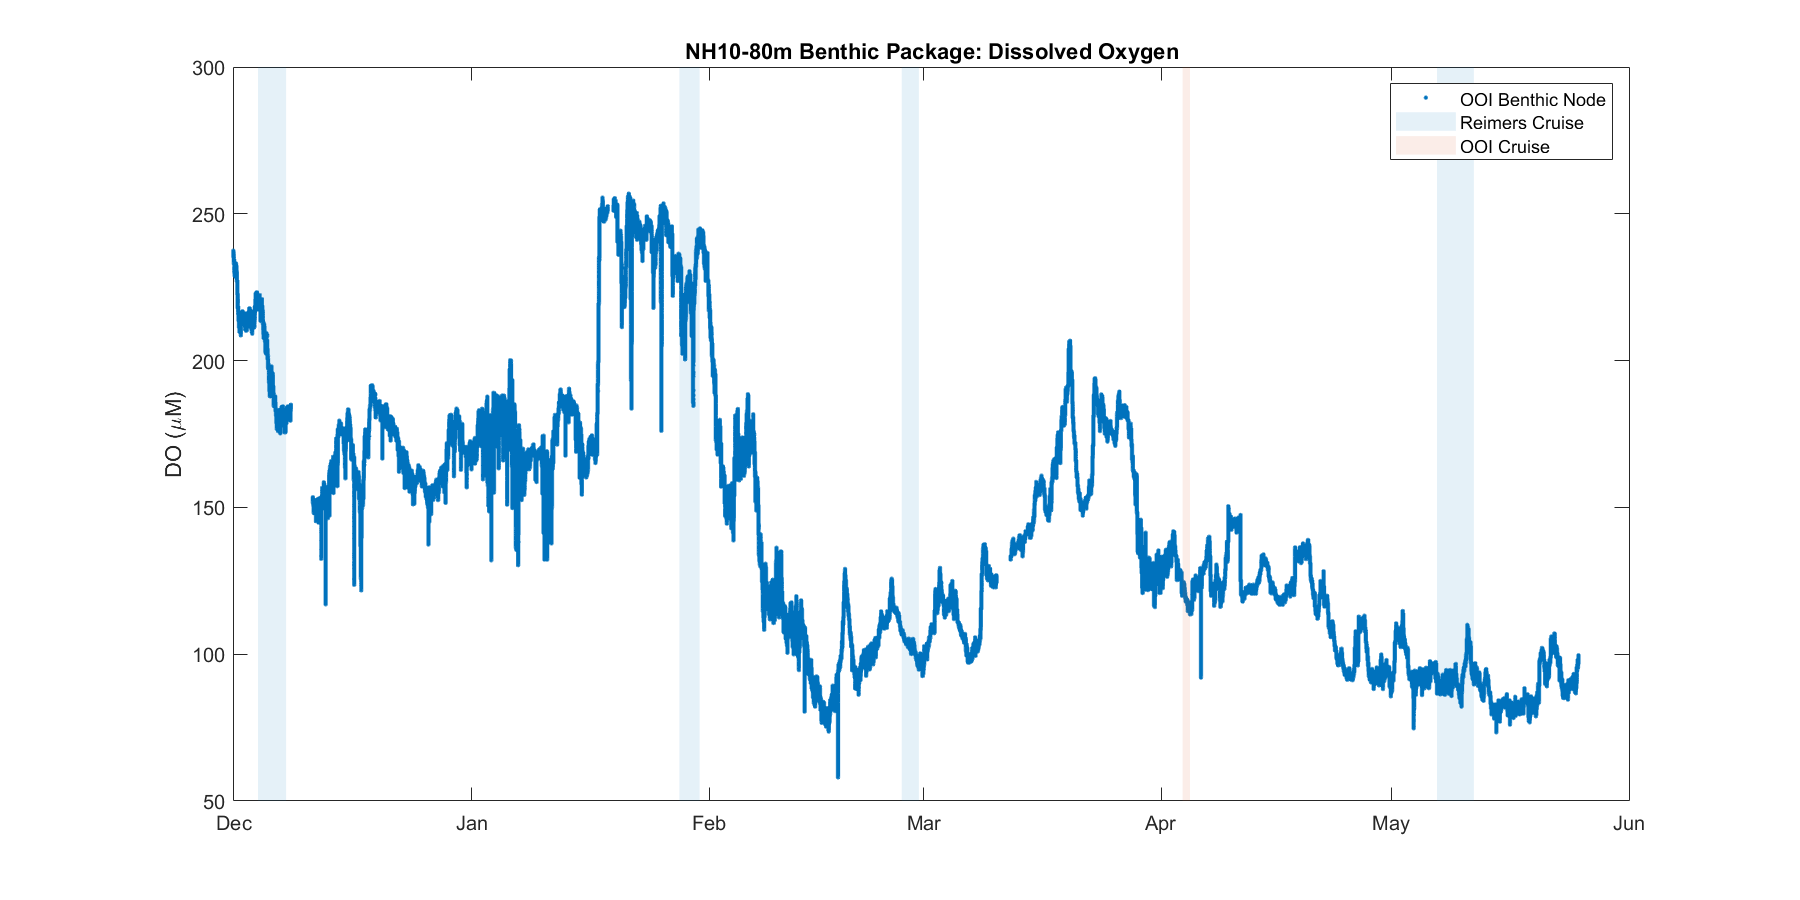

f1=figure('position',[25 25 1200 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)

cd(dir0)
load BNCTD
plot(datenum(BNCTD.dtLOC),BNCTD.DOumolkg.*BNCTD.rho/1000,'.','Color',blue)
hold on

cd(dir1)
load OC201712A_CTD_Water
pgon1 = polyshape([Ev03bot.dt-0.5 Ev03bot.dt-.5 Ev41bot.dt+0.5 Ev41bot.dt+.5],[300 50 50 300]);
plot(pgon1,'FaceColor',blue,'EdgeColor','none','FaceAlpha',0.1)

cd(dir0)
load CTD7_Btl_Sum
pgon5 = polyshape([datenum(CTD7bot.dtLOC)-0.5 datenum(CTD7bot.dtLOC)-.5 datenum(CTD7bot.dtLOC)+0.5 datenum(CTD7bot.dtLOC)+.5],[300 50 50 300]);
plot(pgon5,'FaceColor',red,'EdgeColor','none','FaceAlpha',0.1)

cd(dir2)
load OC201801A_CTD_Water
pgon2 = polyshape([Ev04bot.dt-0.5 Ev04bot.dt-.5 Ev21bot.dt+0.5 Ev21bot.dt+.5],[300 50 50 300]);
plot(pgon2,'FaceColor',blue,'EdgeColor','none','FaceAlpha',0.1)

cd(dir3)
load OC201802B_CTD_Water
pgon3 = polyshape([Ev02bot.dt-0.5 Ev02bot.dt-.5 Ev17bot.dt+0.5 Ev17bot.dt+.5],[300 50 50 300]);
plot(pgon3,'FaceColor',blue,'EdgeColor','none','FaceAlpha',0.1)

cd(dir4)
load OC1805_BottleSum
%Find first and last cast and change events 
pgon4 = polyshape([datenum(Ev02bot.dtLOC)-0.5 datenum(Ev02bot.dtLOC)-.5 datenum(Ev39bot.dtLOC)+0.5 datenum(Ev39bot.dtLOC)+.5],[300 50 50 300]);
plot(pgon4,'FaceColor',blue,'EdgeColor','none','FaceAlpha',0.1)

datetick
ylim([50 300])
xlim([datenum(2017,12,01) datenum(2018,06,01)])
title('NH10-80m Benthic Package: Dissolved Oxygen') 
ylabel('DO (\muM)')
legend('OOI Benthic Node','Reimers Cruise','OOI Cruise')

FIgure 1: Dissolved Oxygen from the Benthic Package on the Oregon Shelf with Reimers' Cruises shaded in blue and an OOI Cruise shaded in red. 

## CTD Cast Data from SKQ201808S

Load CTD Cast Data collected from 80 m from SKQ201808S Cruise (OOI cruise) to use in data validation.

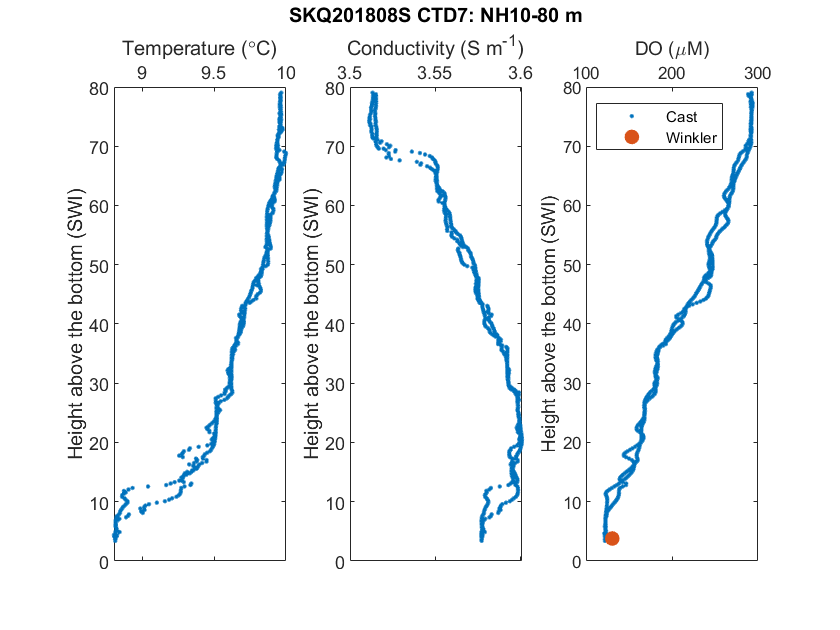

cd(dir0)
load CTD7.mat %Only 80 m cast off Newport Line 
load CTD7_Btl_Sum.mat

botz = 82; %From CTD Header File 
mlL2uM = 44.661; %convert ml/l to uM of DO

figure
subplot(1,3,1)
plot(nanmean([CTD7.temp1 CTD7.temp2],2),botz - CTD7.SWz,'.')
ax = gca;
ax.XAxisLocation = 'top';
ylabel('Height above the bottom (SWI)')
xlabel('Temperature (\circC)')

subplot(1,3,2)
plot(nanmean([CTD7.cond1 CTD7.cond2],2),botz -CTD7.SWz,'.')
ax = gca;
ax.XAxisLocation = 'top';
ylabel('Height above the bottom (SWI)')
xlabel('Conductivity (S m^-^1)')
title('SKQ201808S CTD7: NH10-80 m')

subplot(1,3,3)
plot(CTD7.DO*mlL2uM,botz -CTD7.SWz,'.')
hold on
plot(CTD7bot.DOwink*mlL2uM,botz - CTD7bot.SWz,'.','MarkerSize',25)
ax = gca;
ax.XAxisLocation = 'top';
legend('Cast','Winkler','Location','NW')
ylabel('Height above the bottom (SWI)')
xlabel('DO (\muM)')

Figure 2: Temperature, conductivity and dissolved oxygen (DO) from a CTD cast at NH10 (80m) during an OOI cruise. Niskin bottles were fired in the benthic boundary layer and Winkler titrations were done for additional DO comparisons.  

##  Load in Benthic Node Data and CTD casts from Oceanus Cruises

Load in CTD data from the Oregon Shelf Bnethic Package and from 4 Reimers Cruises for data validation. The CTD casts where usually within 500 m of the Oregon Shelf Benthic Package (NH-10). The CTD cast data used in comparison is from the deepest part of the CTD cast. This is usually about 2-4 meters off the seafloor and was laregely dependent on sea state conditions.    

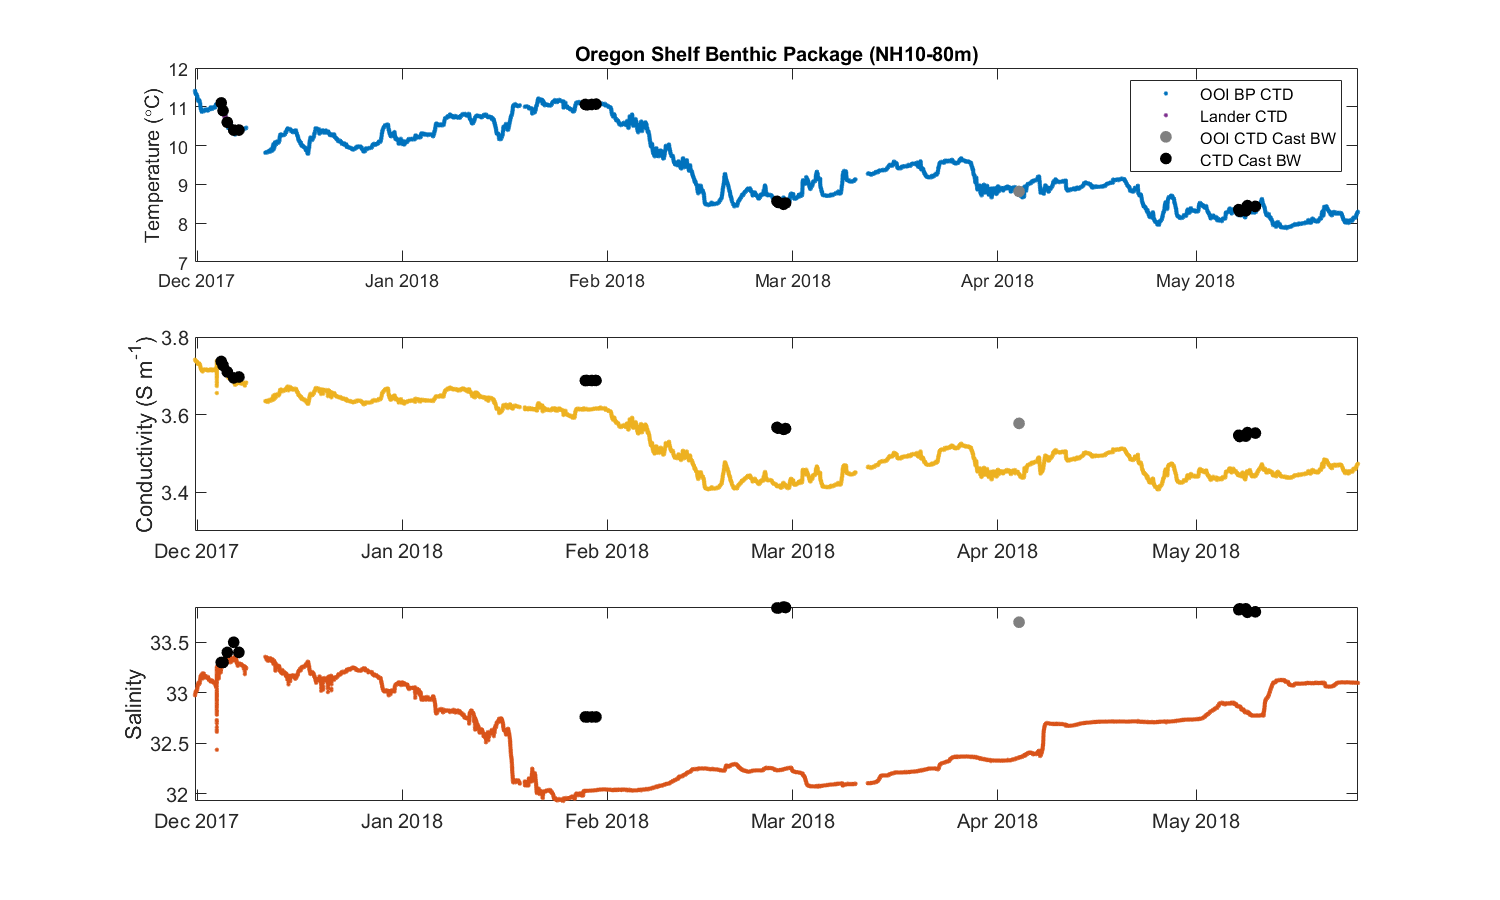


f1=figure('position',[25 25 1000 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)

ms = 20; %set markersize
ax1 = subplot(3,1,1);
plot(BNCTD.dtLOC,BNCTD.temp,'.','Color',blue)
hold on %Cruise OC1712
cd(dir1Ev2)
load Ev2CTD
plot(Ev2CTD.dtLOC,Ev2CTD.temp,'.','Color',purple)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.temp,'.','MarkerSize',ms,'Color',grey)
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.temp,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.temp,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.temp,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.temp,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.temp,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.temp,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.temp,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.temp,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.temp,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.temp,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.temp,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.temp,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.temp,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.temp,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.temp,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.temp,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.temp,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.temp,'.k','MarkerSize',ms)
ylabel('Temperature (\circC)')
axis tight
ylim([7 12])
legend('OOI BP CTD','Lander CTD','OOI CTD Cast BW','CTD Cast BW','Location','NE')
title('Oregon Shelf Benthic Package (NH10-80m)')

ax2 = subplot(3,1,2);
plot(BNCTD.dtLOC,BNCTD.cond,'.','Color',yellow)
hold on %Cruise OC1712
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.cond,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.cond,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.cond,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.cond,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.cond,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.cond,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.cond,'.k','MarkerSize',ms)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.cond,'.','MarkerSize',ms,'Color',grey)
ylabel('Conductivity (S m^-^1)')
axis tight
ylim([3.3 3.8])

ax3 = subplot(3,1,3);
plot(BNCTD.dtLOC,BNCTD.sal,'.','Color',red)
hold on %Cruise OC1712
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.sal,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.sal,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.sal,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.sal,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.sal,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.sal,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.sal,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.sal,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.sal,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.sal,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.sal,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.sal,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.sal,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.sal,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.sal,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.sal,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.sal,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.sal,'.k','MarkerSize',ms)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.sal,'.','MarkerSize',ms,'Color',grey)
ylabel('Salinity')
axis tight
linkaxes([ax1,ax2,ax3],'x')

FIgure 3: Temperature (top panel), conductivity (middle panel) and salinity (bottom panel) from the Oregon Shelf Benthic Package for December 2017 through end of May 2018. Filled circles indicate bottom water (BW) CTD data collected during a Reimers Cruise (black circles) and OOI cruise (grey circles). 

What is going on in the salinity plot? Check to see what stream that is plotting. Also, check cond,temp to salinity with independent code.

## Check the OOI function that converts conductivity to salinity 

Qucik check to see if the salinity difference is because of an error in the OOI code converting conductivity to salinity. 

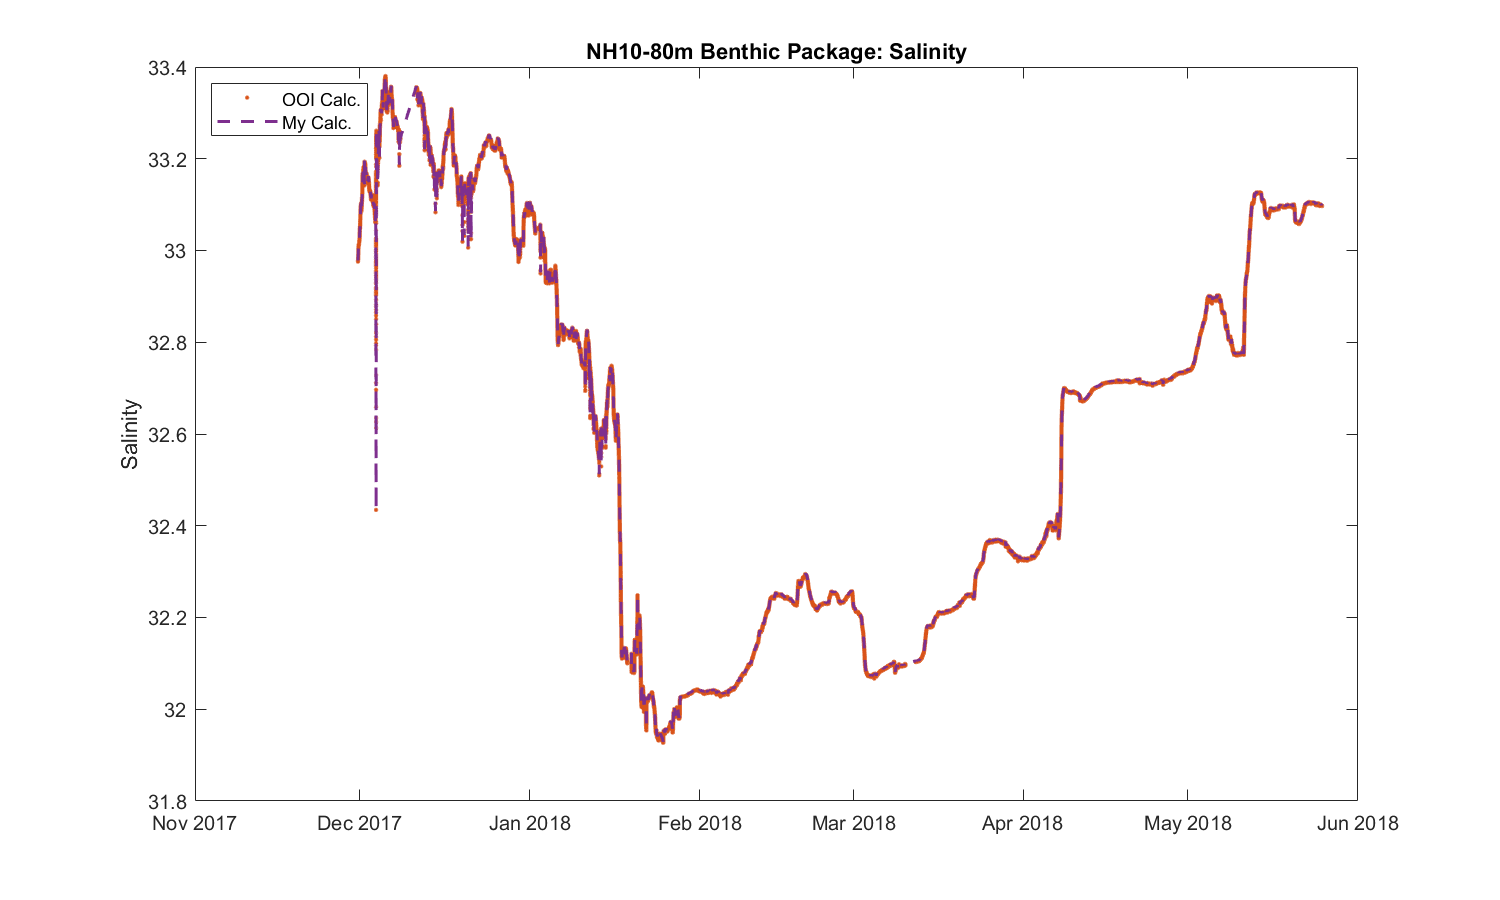

%% Convert temp and conductivity to salinity using established function 

Saltest = [];
for i = 1:length(BNCTD.sal);
    Saltest(i) = sal78( BNCTD.pres(i) , BNCTD.temp(i) , BNCTD.cond(i)*10 , 42.914 , 0 );
end

%% Check the OOI Salinity calculation code

f1=figure('position',[25 25 1000 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)
plot(BNCTD.dtLOC,BNCTD.sal,'.','Color',red)
hold on %Cruise OC1712
plot(BNCTD.dtLOC,Saltest,'--','Linewidth',1.5,'Color',purple)
legend('OOI Calc.','My Calc.','Location','NW')
title('NH10-80m Benthic Package: Salinity') 
ylabel('Salinity')

Figure 4: Calculated salinity from temperature and conductivity using the OOI processing code (red) and the MIT processing code (purple).

There is no difference between the two salnity calculation. Therefore, there doesn't seem to be an error in the processing code

## Oregon Shelf Benthic Package: Conductivity Probe Investigation 

The bottom water temperature from shipboard CTD casts matchees the temperature from the Oregon Shelf Benthic Package. The conductivity probe matches up well for the first Reimers Cruise (OC1712A, December 2017) but not for the remaining 3 Remiers Cruises or the OOI cruise. 

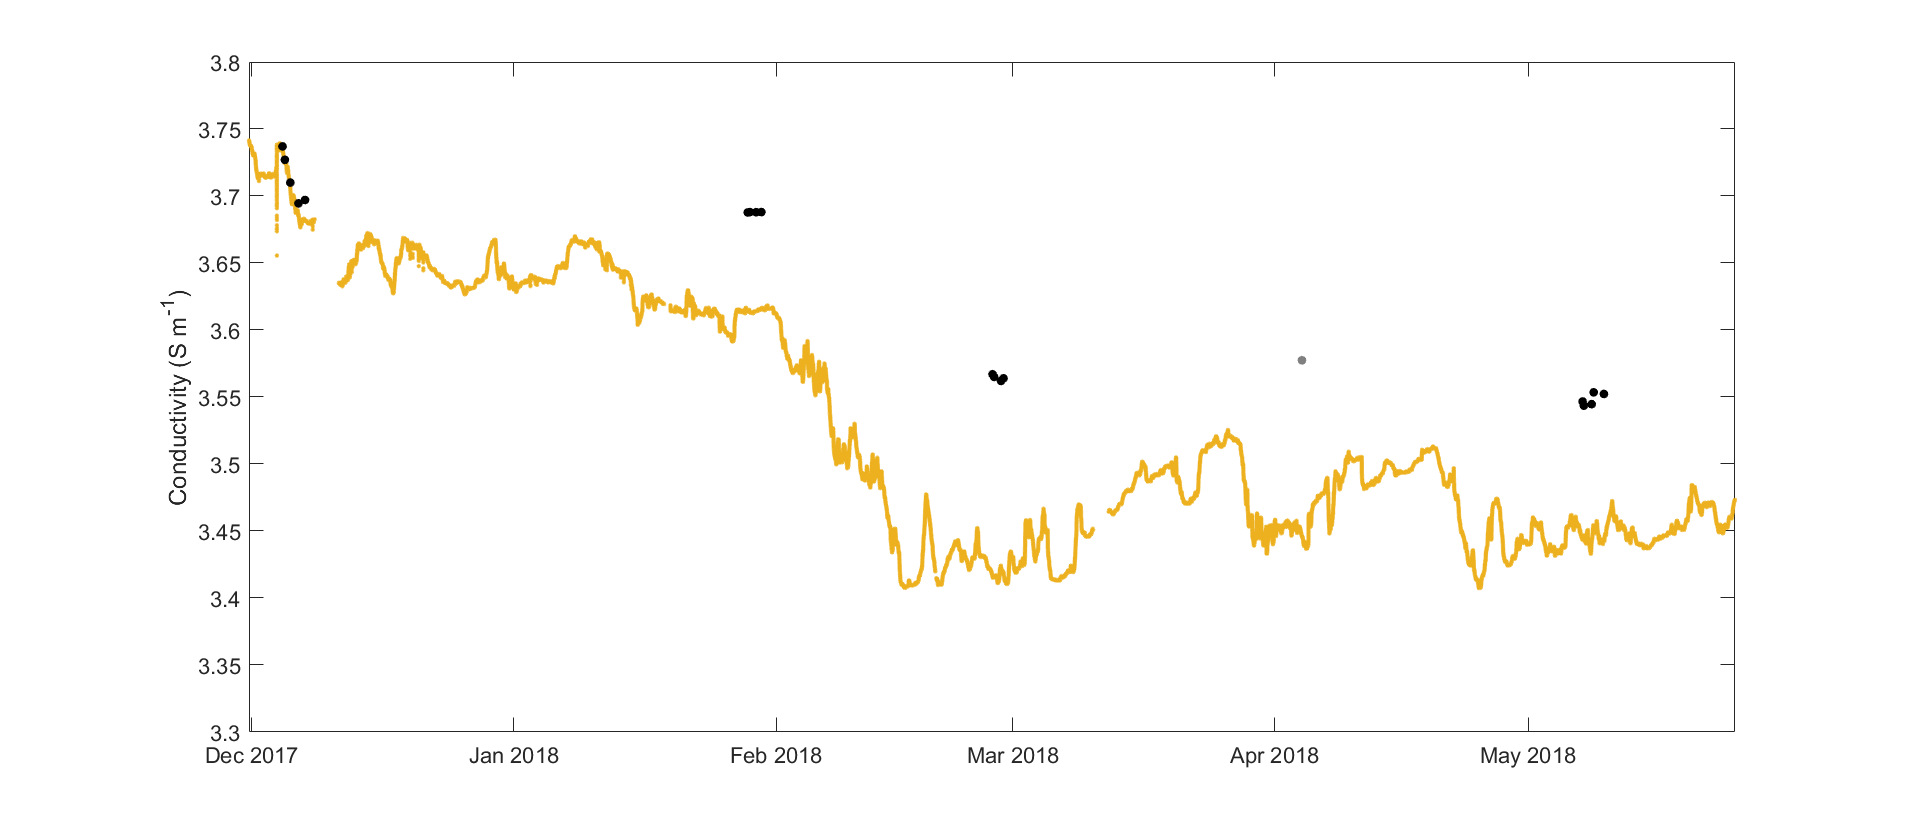

f1=figure('position',[25 25 1400 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)
ms = 15; %set markersize

plot(BNCTD.dtLOC,BNCTD.cond,'.','Color',yellow)
hold on %Cruise OC1712
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.cond,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.cond,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.cond,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.cond,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.cond,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.cond,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.cond,'.k','MarkerSize',ms)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.cond,'.','MarkerSize',ms,'Color',grey)
ylabel('Conductivity (S m^-^1)')
axis tight
ylim([3.3 3.8])

Figure 5 shows that after the brief power outage in Dec 2017, the conductivity at the Oregon Shelf Benthic Package was consistently lower than the bottom water conductivity measured from CTD casts (filled circles

## The benthic node conductivity was then adjusted using an average offset from the bottom water conductivity measured from CTD casts. 

The first cruise was before the power outage and matched up well and was not used in the conductivity offset calculation.   

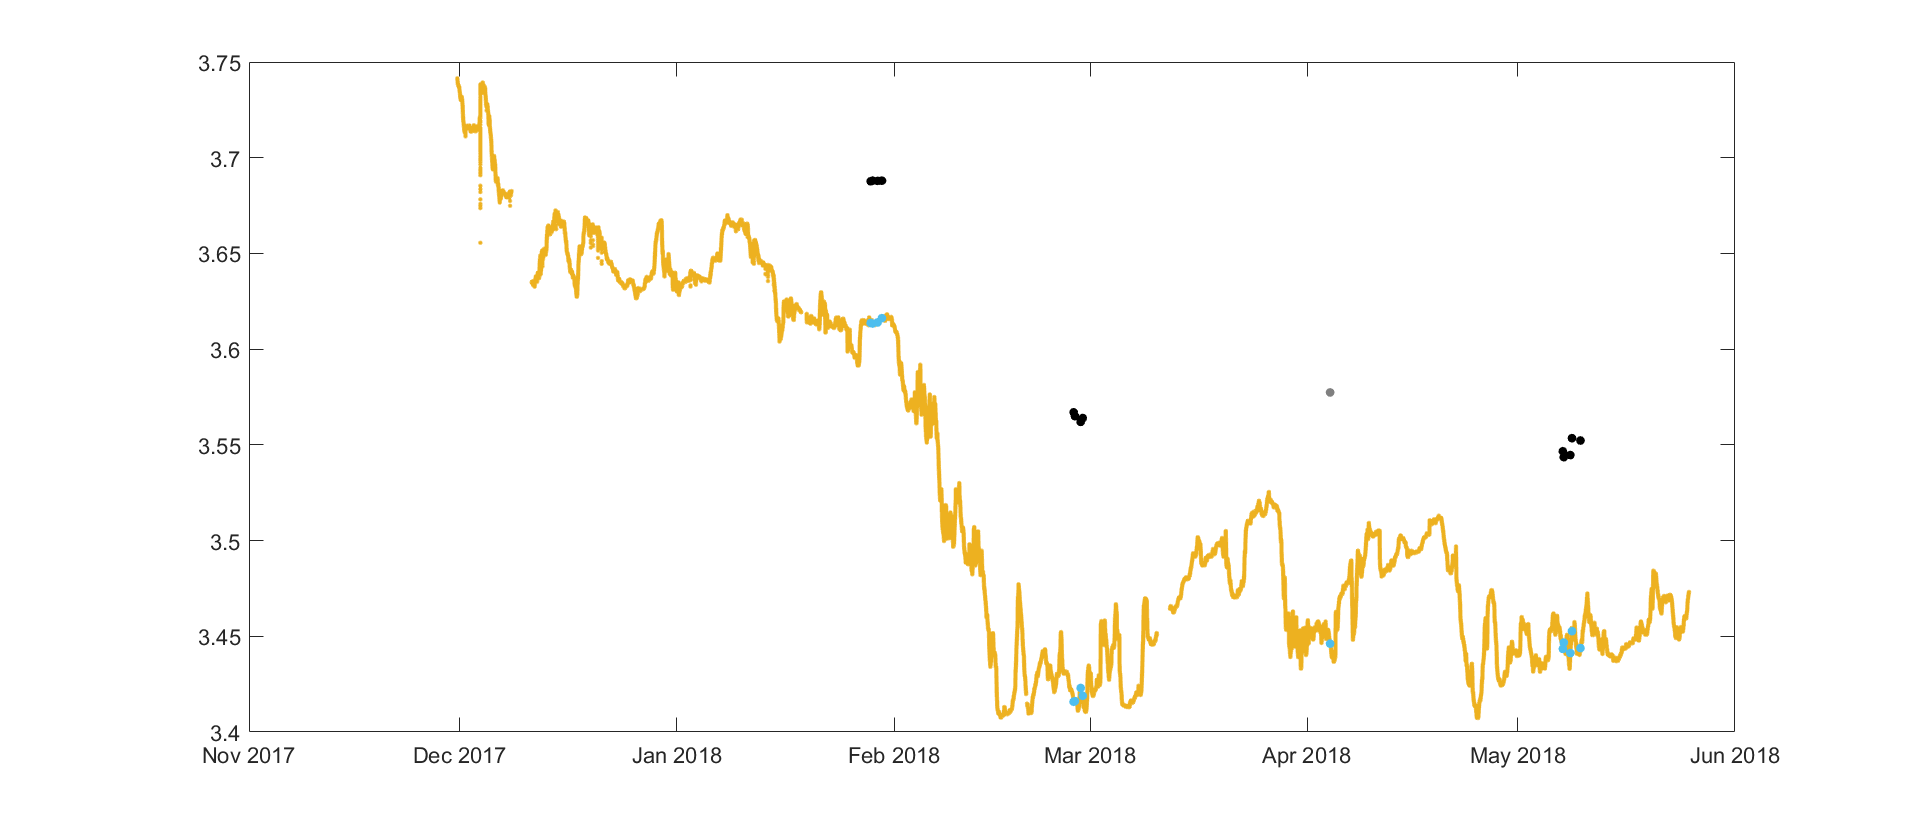

%Adjust cond 
cd(dir2)
load OC201801A_CTD_Water.mat
ind = find(BNCTD.dtLOC >= Ev04bot.dtLOC); 
c1 = Ev04bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev14bot.dtLOC); 
c2 = Ev14bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev20bot.dtLOC); 
c3 = Ev20bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev21bot.dtLOC); 
c4 = Ev21bot.cond - BNCTD.cond(ind(1));


f1=figure('position',[25 25 1400 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)
plot(BNCTD.dtLOC,BNCTD.cond,'.','Color',yellow)
hold on
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.cond,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.cond-c1,'.k','MarkerSize',ms,'Color',cyan)
plot(Ev14bot.dtLOC,Ev14bot.cond-c2,'.k','MarkerSize',ms,'Color',cyan)
plot(Ev20bot.dtLOC,Ev20bot.cond-c3,'.k','MarkerSize',ms,'Color',cyan)
plot(Ev21bot.dtLOC,Ev21bot.cond-c4,'.k','MarkerSize',ms,'Color',cyan)

cd(dir3)
load OC201802B_CTD_Water.mat
ind = find(BNCTD.dtLOC >= Ev02bot.dtLOC); 
c5 = Ev02bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev04bot.dtLOC); 
c6 = Ev04bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev06bot.dtLOC); 
c7 = Ev06bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev17bot.dtLOC); 
c8 = Ev17bot.cond - BNCTD.cond(ind(1));

plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.cond,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.cond,'.k','MarkerSize',ms)
plot(Ev02bot.dtLOC,Ev02bot.cond-c5,'.k','MarkerSize',ms,'Color',cyan)
plot(Ev04bot.dtLOC,Ev04bot.cond-c6,'.k','MarkerSize',ms,'Color',cyan)
plot(Ev06bot.dtLOC,Ev06bot.cond-c7,'.k','MarkerSize',ms,'Color',cyan)
plot(Ev17bot.dtLOC,Ev17bot.cond-c8,'.k','MarkerSize',ms,'Color',cyan)

cd(dir4)
load OC1805_BottleSum.mat
ind = find(BNCTD.dtLOC >= Ev02bot.dtLOC); 
c9 = Ev02bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev07bot.dtLOC); 
c10 = Ev07bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev19bot.dtLOC); 
c11 = Ev19bot.cond - BNCTD.cond(ind(1)); 

ind = find(BNCTD.dtLOC >= Ev21bot.dtLOC); 
c12 = Ev21bot.cond - BNCTD.cond(ind(1));

ind = find(BNCTD.dtLOC >= Ev33bot.dtLOC); 
c13 = Ev33bot.cond - BNCTD.cond(ind(1));

plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.cond,'.k','MarkerSize',ms)
plot(Ev02bot.dtLOC,Ev02bot.cond-c9,'.','MarkerSize',ms,'Color',cyan)
plot(Ev07bot.dtLOC,Ev07bot.cond-c10,'.','MarkerSize',ms,'Color',cyan)
plot(Ev19bot.dtLOC,Ev19bot.cond-c11,'.','MarkerSize',ms,'Color',cyan)
plot(Ev21bot.dtLOC,Ev21bot.cond-c12,'.','MarkerSize',ms,'Color',cyan)
plot(Ev33bot.dtLOC,Ev33bot.cond-c13,'.','MarkerSize',ms,'Color',cyan)

cd(dir0)
load CTD7_Btl_Sum
ind = find(BNCTD.dtLOC >= CTD7bot.dtLOC); 
c14 = CTD7bot.cond - BNCTD.cond(ind(1));
plot(CTD7bot.dtLOC,CTD7bot.cond,'.','MarkerSize',ms,'Color',grey)
plot(CTD7bot.dtLOC,CTD7bot.cond-c14,'.','MarkerSize',ms,'Color',cyan)

Figure 6: Visual check of the points used to calculate the conductivity offset. 

%% Makes the conductivity correction 
cond_off = [c1 c2 c3 c4 c5 c6 c7 c8 c9 c10 c11 c12 c13 c14]';
cond_off_mean = nanmean(cond_off);
cond_off_std = nanstd(cond_off);

%% 11-Dec-2017 07:20:58
poweron = datetime(2017,12,11,07,00,00);
poweron.TimeZone = 'America/Los_Angeles';
indBN = find(BNCTD.dtLOC >= poweron); 

BNCTD.cond2 = BNCTD.cond + cond_off_mean; 




## This section uses the adjusted conductivity to calcualte a corrected salinity, and then uses the corrected salinity to recalculate the dissolved oxygen. 

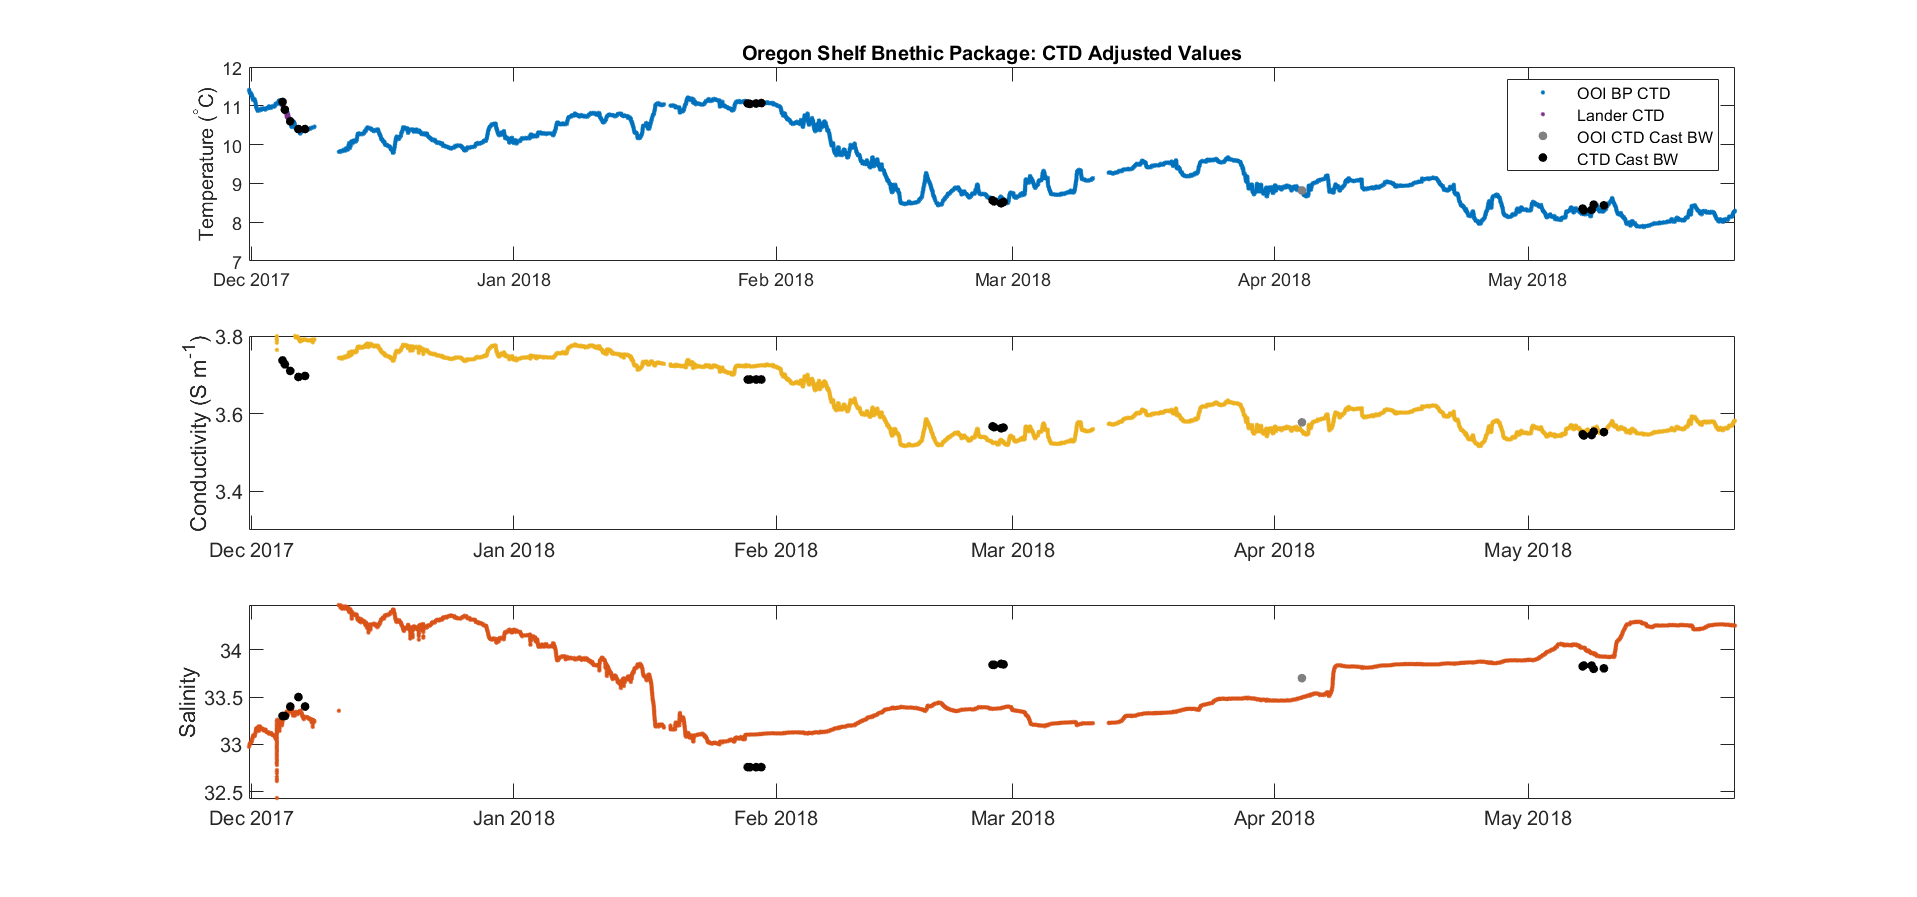

%Adjusts salinity based on adjusted cond
BNCTD.saladj = [];
for i = 1:length(BNCTD.sal);
    BNCTD.saladj(i) = sal78( BNCTD.pres(i) , BNCTD.temp(i) , BNCTD.cond2(i)*10 , 42.914 , 0 );
end
BNCTD.saladj = BNCTD.saladj';

%Adjusts density based on adjusted sal 
BNCTD.rhoadj = [];
for i = 1:length(BNCTD.cond);
    BNCTD.rhoadj(i) = SW_Density(BNCTD.temp(i),'C',BNCTD.saladj(i),'ppt',BNCTD.pres(i)/10,'bar');
end
BNCTD.rhoadj = BNCTD.rhoadj';

BNCTD.condadj = BNCTD.cond2;
BNCTD.saladj(1:indBN(1)) = BNCTD.sal(1:indBN(1));
BNCTD.rhoadj(1:indBN(1)) = BNCTD.rho(1:indBN(1));
BNCTD.condadj(1:indBN(1)) = BNCTD.cond2(1:indBN(1));

f1=figure('position',[25 25 1400 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)

ms = 15; %set markersize
ax1 = subplot(3,1,1);
plot(BNCTD.dtLOC,BNCTD.temp,'.','Color',blue)
hold on %Cruise OC1712
cd(dir1Ev2)
load Ev2CTD
plot(Ev2CTD.dtLOC,Ev2CTD.temp,'.','Color',purple)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.temp,'.','MarkerSize',ms,'Color',grey)
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.temp,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.temp,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.temp,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.temp,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.temp,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.temp,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.temp,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.temp,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.temp,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.temp,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.temp,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.temp,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.temp,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.temp,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.temp,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.temp,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.temp,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.temp,'.k','MarkerSize',ms)
ylabel('Temperature (^\circC)')
axis tight
ylim([7 12])
legend('OOI BP CTD','Lander CTD','OOI CTD Cast BW','CTD Cast BW','Location','NE')
title('Oregon Shelf Bnethic Package: CTD Adjusted Values')

ax2 = subplot(3,1,2);
plot(BNCTD.dtLOC,BNCTD.condadj,'.','Color',yellow)
hold on %Cruise OC1712
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.cond,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.cond,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.cond,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.cond,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.cond,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.cond,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.cond,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.cond,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.cond,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.cond,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.cond,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.cond,'.k','MarkerSize',ms)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.cond,'.','MarkerSize',ms,'Color',grey)
ylabel('Conductivity (S m^-^1)')
axis tight
ylim([3.3 3.8])

ax3 = subplot(3,1,3);
plot(BNCTD.dtLOC,BNCTD.saladj,'.','Color',red)
hold on %Cruise OC1712
cd(dir1)
load OC201712A_CTD_Water.mat
plot(Ev03bot.dtLOC,Ev03bot.sal,'.k','MarkerSize',ms)
plot(Ev12bot.dtLOC,Ev12bot.sal,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.sal,'.k','MarkerSize',ms)
plot(Ev34bot.dtLOC,Ev34bot.sal,'.k','MarkerSize',ms)
plot(Ev41bot.dtLOC,Ev41bot.sal,'.k','MarkerSize',ms)
cd(dir2)
load OC201801A_CTD_Water.mat
plot(Ev04bot.dtLOC,Ev04bot.sal,'.k','MarkerSize',ms)
plot(Ev14bot.dtLOC,Ev14bot.sal,'.k','MarkerSize',ms)
plot(Ev20bot.dtLOC,Ev20bot.sal,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.sal,'.k','MarkerSize',ms)
cd(dir3)
load OC201802B_CTD_Water.mat
plot(Ev02bot.dtLOC,Ev02bot.sal,'.k','MarkerSize',ms)
plot(Ev04bot.dtLOC,Ev04bot.sal,'.k','MarkerSize',ms)
plot(Ev06bot.dtLOC,Ev06bot.sal,'.k','MarkerSize',ms)
plot(Ev17bot.dtLOC,Ev17bot.sal,'.k','MarkerSize',ms)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.sal,'.k','MarkerSize',ms)
plot(Ev07bot.dtLOC,Ev07bot.sal,'.k','MarkerSize',ms)
plot(Ev19bot.dtLOC,Ev19bot.sal,'.k','MarkerSize',ms)
plot(Ev21bot.dtLOC,Ev21bot.sal,'.k','MarkerSize',ms)
plot(Ev33bot.dtLOC,Ev33bot.sal,'.k','MarkerSize',ms)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.sal,'.','MarkerSize',ms,'Color',grey)
ylabel('Salinity')
axis tight
linkaxes([ax1,ax2,ax3],'x')

Figure 7: The adjusted conductivity and resulting salinity for the CTD on the Oregon Shel Benthic Package. 

## Correcting DO for temp, salinity and pressure using the adjusted salinity and density values

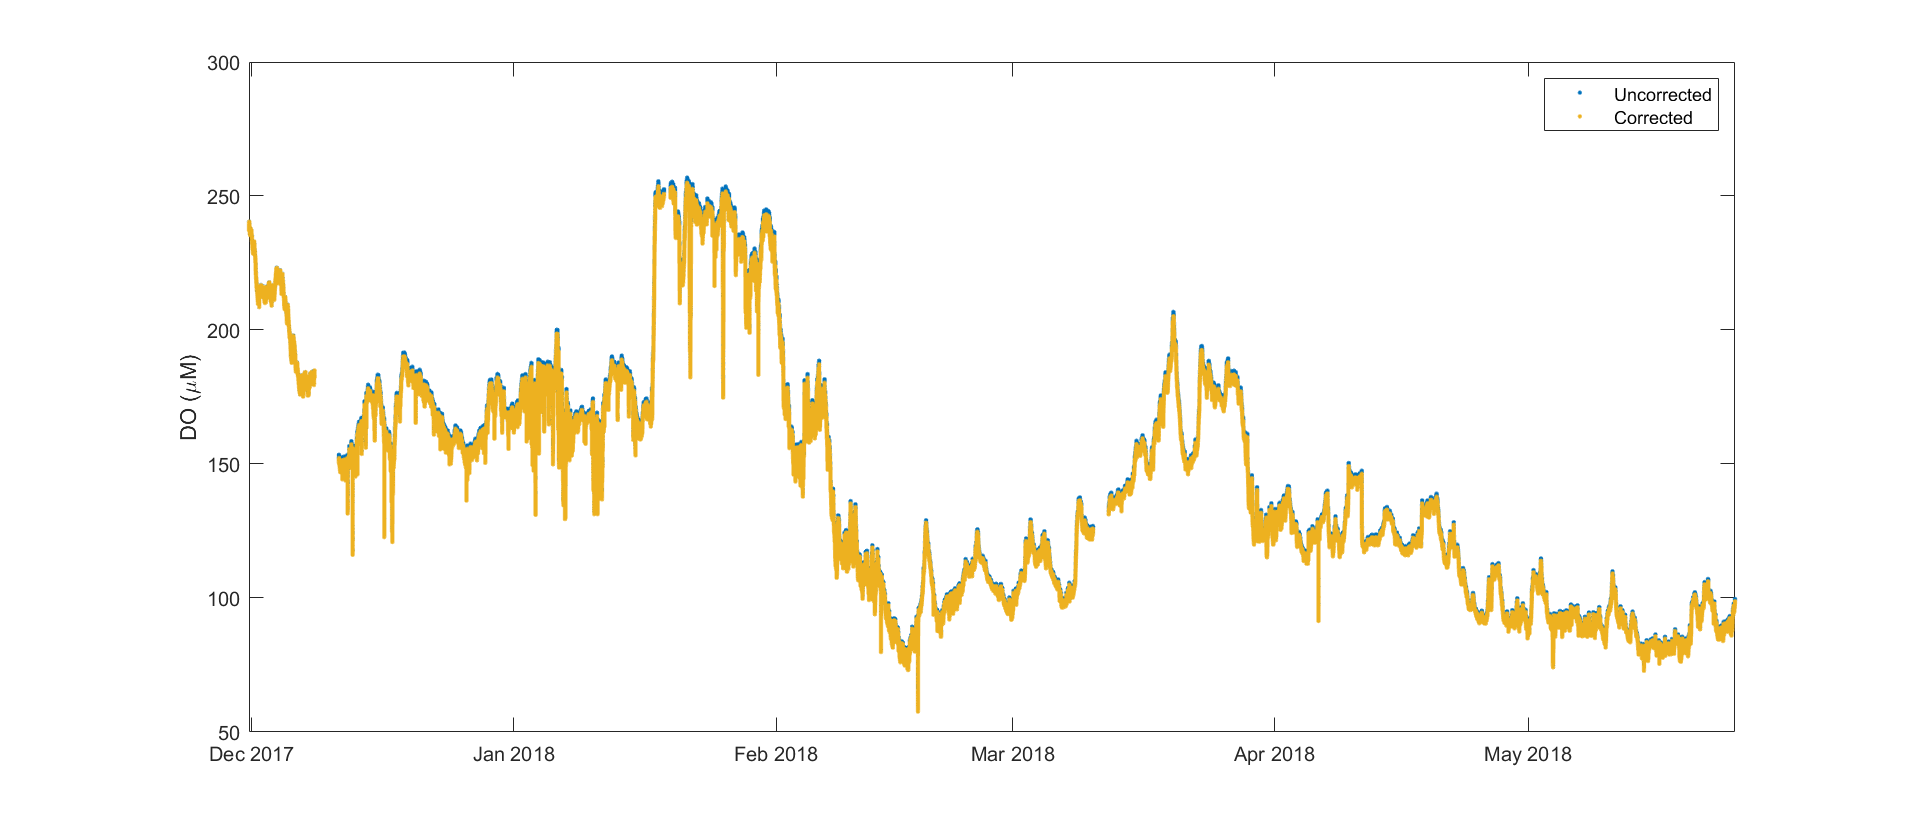

%% Level 1 DO correction for pressure and salinity to compute L2 pressure-salinity corrected DO
% Pressure correction average is a factor of 1.0026

DOkg = (1 + (0.032*BNCTD.pres)/1000).* (BNCTD.DOumolL*1000./BNCTD.rhoadj);
%
% Salinity correction (Garcia and Gordon, 1992, combined fit):
% Salinity correction about 0.8
S0 = 0;
ts = log((298.15-BNCTD.temp)./(273.15+BNCTD.temp));
B0 = -6.24097e-3;
B1 = -6.93498e-3;
B2 = -6.90358e-3;
B3 = -4.29155e-3;
C0 = -3.11680e-7;
Bts = B0 + B1*ts + B2*ts.^2 + B3*ts.^3;
DO = exp((BNCTD.saladj-S0).*Bts + C0*(BNCTD.saladj.^2-S0.^2)).* DOkg;
BNCTD.DOuM = DO.*BNCTD.rhoadj/1000; %pressure/temp/salinity corrected using adjusted salinity. 

f1=figure('position',[25 25 1400 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)
ms = 15; %set markersize
plot(BNCTD.dtLOC,BNCTD.DOumolkg.*BNCTD.rho/1000,'.','Color',blue)
hold on
plot(BNCTD.dtLOC,BNCTD.DOuM,'.','Color',yellow)
legend('Uncorrected','Corrected')
ylabel('DO (\muM)')
axis tight
ylim([50 300])

Figure 8: Uncorrected versus corrected dissolved oxygen. The adjustments in conductivity and then salinity did not have much of an affect on the overall dissolved oxygen concentrations. 

## Comparing all of the different dissolved oxygen data streams

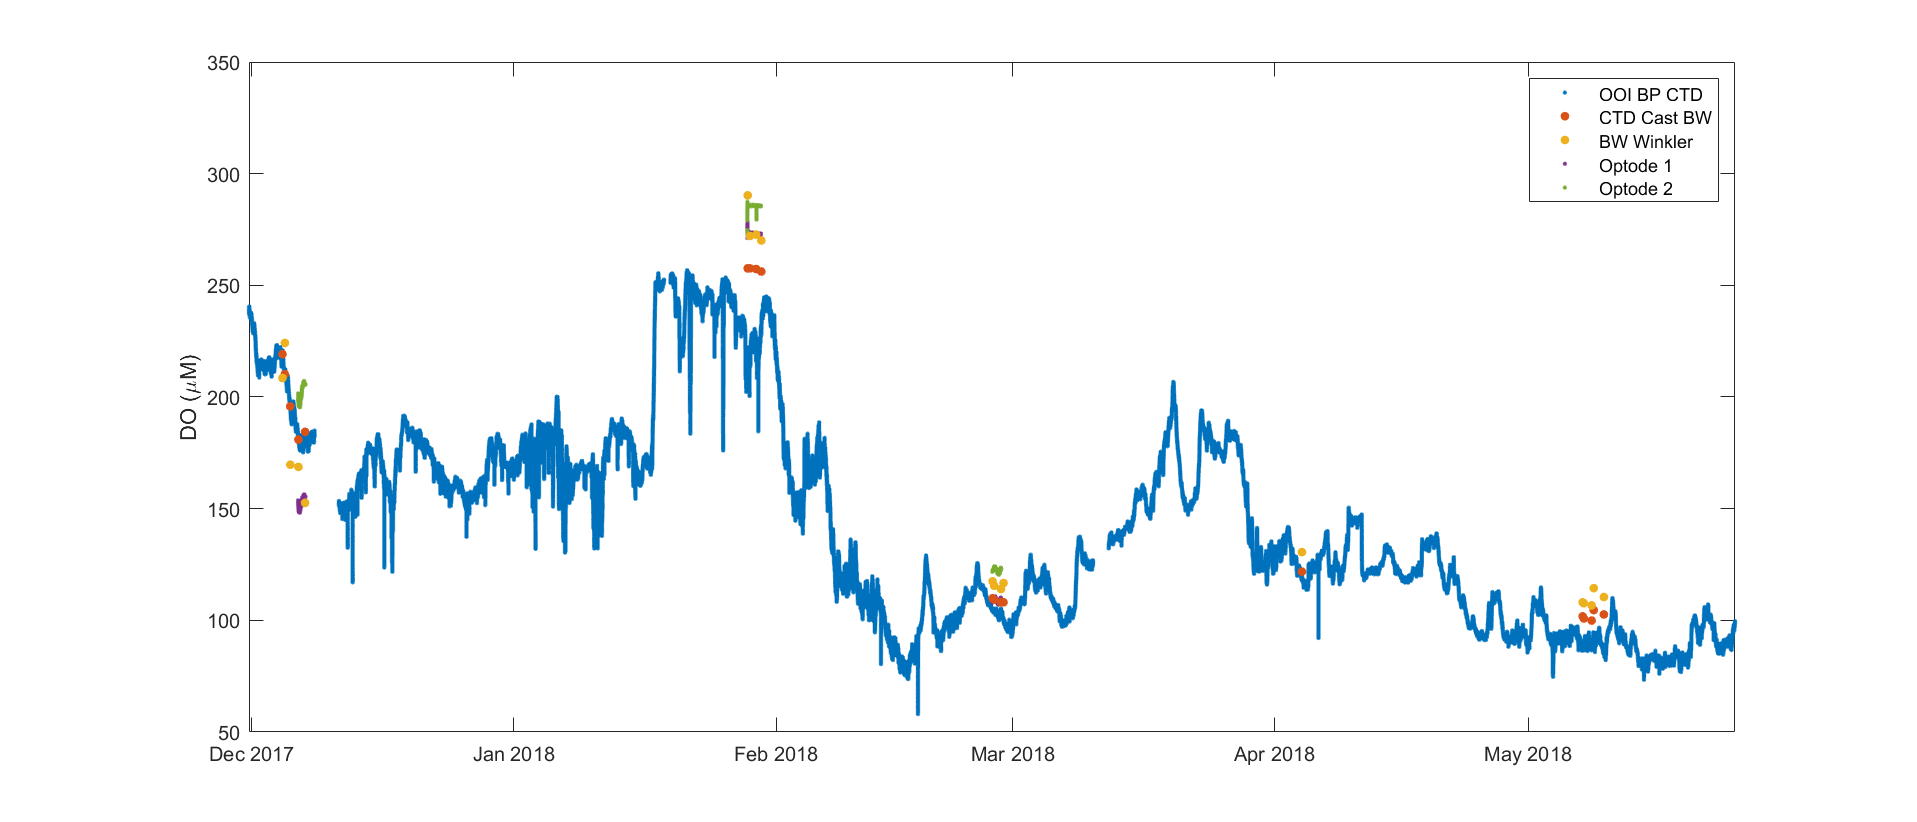

%Offset is ~38 u
mlL2uM = 44.661; %ml/L of DO to uM

f1=figure('position',[25 25 1400 600]);
set(f1,'Color','w')
set(gca,'FontName','Arial','Fontsize',12)
ms = 15; %set markersize
plot(BNCTD.dtLOC,BNCTD.DOumolkg.*BNCTD.rho/1000,'.','Color',blue)
hold on %Cruise OC1712
% plot(BNCTD.dtLOC,DOL,'.','Color',yellow)
cd(dir0)
load CTD7_Btl_Sum
plot(CTD7bot.dtLOC,CTD7bot.DOctd*mlL2uM,'.','MarkerSize',ms,'Color',red) 
plot(CTD7bot.dtLOC,CTD7bot.DOwink*mlL2uM,'.','MarkerSize',ms,'Color',yellow)
cd(dir1)
load OC201712A_CTD_Water.mat
load Ev33DOoptodes.mat
plot(opt1.dtLOC,opt1.DOconc,'.','Color',purple)
plot(opt2.dtLOC,opt2.DOconc,'.','Color',green)
plot(Ev03bot.dtLOC,Ev03bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev12bot.dtLOC,Ev12bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev19bot.dtLOC,Ev19bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev34bot.dtLOC,Ev34bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev41bot.dtLOC,Ev41bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev03bot.dtLOC,Ev03bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev12bot.dtLOC,Ev12bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev19bot.dtLOC,Ev19bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev34bot.dtLOC,Ev34bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev41bot.dtLOC,Ev41bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
cd(dir2)
load OC201801A_CTD_Water.mat
load DOopts.mat
plot(opt1.dtLOC,opt1.DOconc,'.','Color',purple)
plot(opt2.dtLOC,opt2.DOconc,'.','Color',green)
plot(Ev04bot.dtLOC,Ev04bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev14bot.dtLOC,Ev14bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev20bot.dtLOC,Ev20bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev21bot.dtLOC,Ev21bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev04bot.dtLOC,Ev04bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev14bot.dtLOC,Ev14bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev20bot.dtLOC,Ev20bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev21bot.dtLOC,Ev21bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
cd(dir3)
load OC201802B_CTD_Water.mat
load DOopts.mat
ind3 = 450:length(opt1.dt) - 650;
plot(opt1.dtLOC(ind3),opt1.DOconc(ind3),'.','Color',purple)
plot(opt2.dtLOC(ind3),opt2.DOconc(ind3),'.','Color',green)
plot(Ev02bot.dtLOC,Ev02bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev04bot.dtLOC,Ev04bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev06bot.dtLOC,Ev06bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev17bot.dtLOC,Ev17bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev02bot.dtLOC,Ev02bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev04bot.dtLOC,Ev04bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev06bot.dtLOC,Ev06bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev17bot.dtLOC,Ev17bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
cd(dir4)
load OC1805_BottleSum.mat
plot(Ev02bot.dtLOC,Ev02bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev07bot.dtLOC,Ev07bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev19bot.dtLOC,Ev19bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev21bot.dtLOC,Ev21bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev33bot.dtLOC,Ev33bot.DOctd(2),'.','MarkerSize',ms,'Color',red)
plot(Ev02bot.dtLOC,Ev02bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev07bot.dtLOC,Ev07bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev19bot.dtLOC,Ev19bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev21bot.dtLOC,Ev21bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
plot(Ev33bot.dtLOC,Ev33bot.DOwink(2),'.','MarkerSize',ms,'Color',yellow)
ylabel('DO (\muM)')
axis tight
ylim([50 350])
legend('OOI BP CTD','CTD Cast BW','BW Winkler','Optode 1','Optode 2','Location','NE')

Figure 9: Dissoved oxygen (DO) from the Oregon Shelf Benthic Package (blue) from December 2017 to the end of the May 2018. Yellow circles indicated bottom water winkler DO values and red circles indicate bottom water CTD winkler values.Yellow and purple lines indicate optode data that has not been salinity and pressure corrected. Still needs work to make sure that all oxygen values being compared are in concentration units that have been pressure, temperature, and salinity corrected. 